HOMEWORK PROBLEM 6

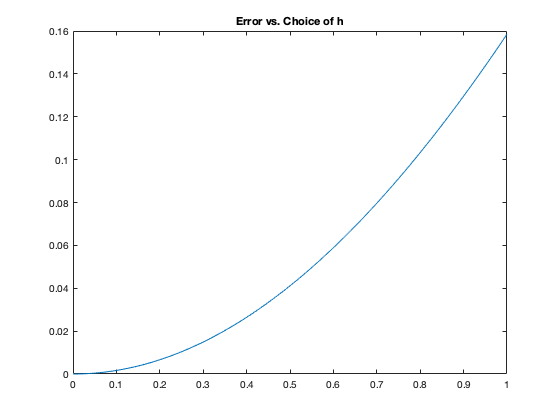

%Add findFDCoefs file to pathway
addpath("/Users/grantpoulsen/Desktop/Numerical Analysis Code/");

% Functions
u = @(x) sin(x);
du = @(x) cos(x);

% Try h elements from .001 to 1 by 1000ths
h = linspace(.001,1,1000);

% Vector For Calculating Error
error = zeros(1,length(h));

% We'll use xbar = pi for simplicity
xbar = pi;

% Actual Derivative
actual = du(xbar);

% Consider Approximations With Different h's & their respective
% accumulating error
for i = 1: length(h)

    % Make xvals & fvals off guess of h
    xvals = [pi- h(i); pi + h(i)];
    fvals = u(xvals);
    
    % Find Coefs
    coefs = findFDCoefs(1,xbar,xvals);
    
    % Find Approximation
    approxDer = dot(coefs,fvals);
    
    % Find Error
    error(1,i) = abs(approxDer - actual);

end

% Plot Error vs. h
plot(h,error);
title("Error vs. Choice of h");


% Find h resulting in Minimum Error
minError = error(1,1);
indexMin = 1;

% Minimization Loop
for i = 1: length(h)
    
    if(error(1,i) < minError)
        
        minError = error(1,i);
        indexMin = i;
    end
end

% Conclusion
disp("Our Minimum Error From Guessing is: " + error(1,indexMin));

Our Minimum Error From Guessing is: 1.6667e-07


disp("It follows that h must be approximately: " + h(1,indexMin));

It follows that h must be approximately: 0.001


disp("Epsilon must approximately be: " + ((h(1,indexMin))^3)/3);

Epsilon must approximately be: 3.3333e-10


It seems that the minimum would be (1/30)^9 given our error analysis. 